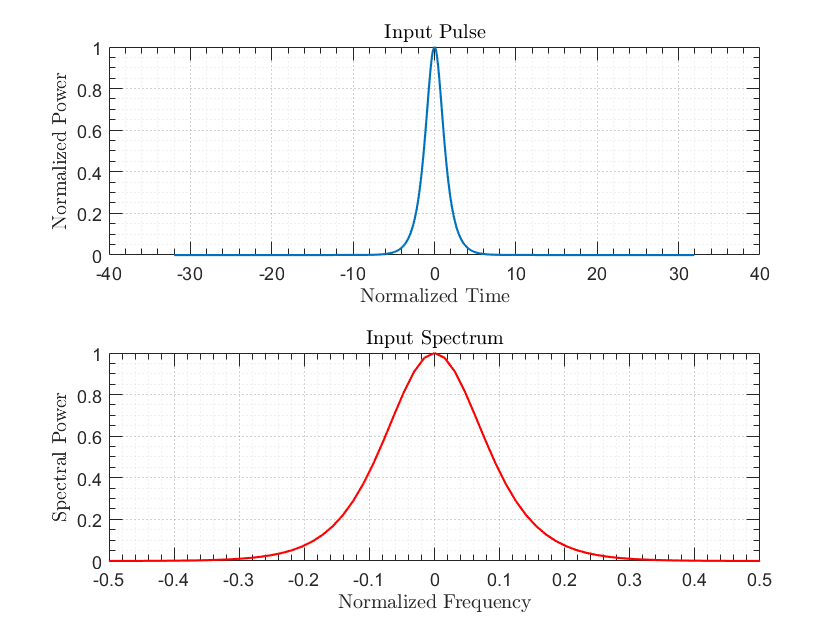

% SSFM code for solving the normalized NLS equation
%  By G. P. Agrawal for the 6th edition of NLFO book

fiblen = 1;                      % Fiber length (in units of L_D)
beta2 = -1;                       % Sign of GVD parameter beta_2
N = 1;                           % Soliton order


% --- simulation parameters --- %
nt = 1024; Tmax = 32;           % FFT points and window size
step_num = round(20*fiblen*N^2); % Z steps
deltaz = fiblen/step_num;        % Z step size
dtau = (2*Tmax)/nt;                 % Tau step size

tau = (-nt/2:nt/2-1)*dtau;        % Time array
omega = fftshift(-nt/2:nt/2-1)*(pi/Tmax);   % Omega array
uu = sech(tau);                  % Input pulse

% --- Plot input pulse and spectrum --- %
temp = fftshift(ifft(uu));       % Fourier transform
spect = abs(temp).^2;            % Input spectrum
spect = spect./max(spect);        % Normalize
freq = fftshift(omega)/(2*pi);   % Freq array

tiledlayout(2,1)
nexttile(1)
plot(tau, abs(uu), 'LineWidth', 1.05);
title('Input Pulse',"Interpreter","latex");
xlabel('Normalized Time', "Interpreter","latex");
ylabel('Normalized Power',"Interpreter","latex");
box on
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
'TickLength', [0.02, 0.04], ...
'LineWidth', 0.5);
grid minor; % Adds minor grid lines
set(gca, 'GridLineStyle', ':', ...    % Dashed grid lines
         'GridColor', [0.5, 0.5, 0.5], ... % Gray grid lines
         'GridAlpha', 0.7, ...         % Transparency of major grid
         'MinorGridLineStyle', ':', ...% Dotted minor grid lines
         'MinorGridColor', [0.8, 0.8, 0.8], ... % Light gray minor grid
         'MinorGridAlpha', 0.5);       % Transparency of minor grid
ylim([0 1])

nexttile(2)
plot(freq, spect,'LineWidth', 1.05, 'Color', [1 0 0]);
title('Input Spectrum',"Interpreter","latex");
xlabel('Normalized Frequency', "Interpreter","latex");
ylabel('Spectral Power',"Interpreter","latex");
box on
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
'TickLength', [0.02, 0.04], ...
'LineWidth', 0.5);
grid minor; % Adds minor grid lines
set(gca, 'GridLineStyle', ':', ...    % Dashed grid lines
         'GridColor', [0.5, 0.5, 0.5], ... % Gray grid lines
         'GridAlpha', 0.7, ...         % Transparency of major grid
         'MinorGridLineStyle', ':', ...% Dotted minor grid lines
         'MinorGridColor', [0.8, 0.8, 0.8], ... % Light gray minor grid
         'MinorGridAlpha', 0.5);       % Transparency of minor grid
axis([-0.5 0.5 0 inf]) 
hold off

% Dispersive phase shifts
dispersion = exp(0.5i*beta2*omega.^2*deltaz); % phase factor
hhz = 1i*N^2*deltaz;                          % nonlinear phase factor

 %*********[ Beginning of MAIN Loop]***********
 % scheme: 1/2N-> D-> 1/2N; first half step nonlinear
 temp = uu.*exp(abs(uu).^2.*hhz/2);
 % note hhz/2
 for n=1:step_num
     f_temp = ifft(temp).*dispersion;
     uu = fft(f_temp);
     temp = uu.*exp(abs(uu).^2.*hhz);
 end
 uu = temp.*exp(-abs(uu).^2.*hhz/2); % Final field
 %***************[ End of MAIN Loop ]**************
 
 % ---Plot output pulse shape and spectrum --- %
 temp = fftshift(ifft(uu)); 
 % Fourier transform
 spect = abs(temp).^2;
 spect = spect./max(spect);

tiledlayout(2,1)

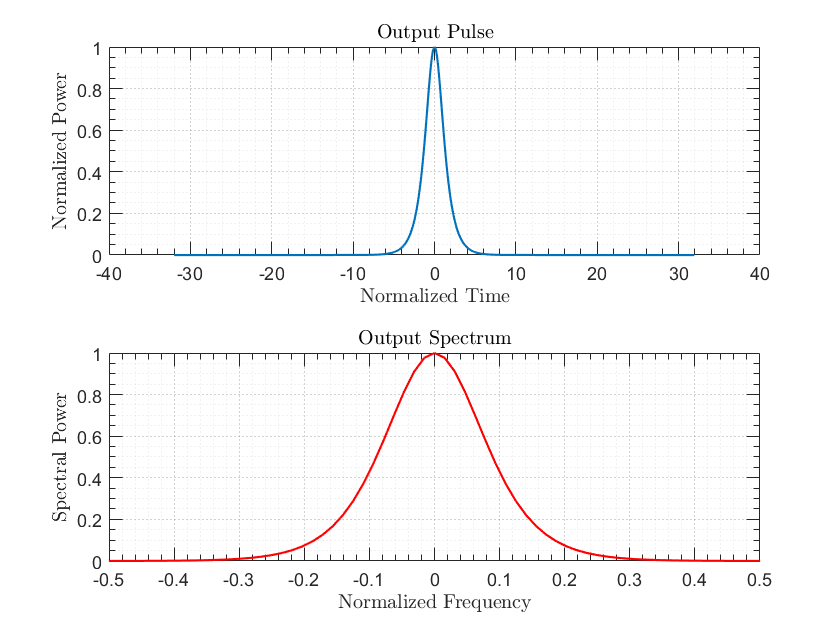

nexttile(1)
plot(tau, abs(uu), 'LineWidth', 1.05);
title('Output Pulse',"Interpreter","latex");
xlabel('Normalized Time', "Interpreter","latex");
ylabel('Normalized Power',"Interpreter","latex");
box on
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
'TickLength', [0.02, 0.04], ...
'LineWidth', 0.5);
grid minor; % Adds minor grid lines
set(gca, 'GridLineStyle', ':', ...    % Dashed grid lines
         'GridColor', [0.5, 0.5, 0.5], ... % Gray grid lines
         'GridAlpha', 0.7, ...         % Transparency of major grid
         'MinorGridLineStyle', ':', ...% Dotted minor grid lines
         'MinorGridColor', [0.8, 0.8, 0.8], ... % Light gray minor grid
         'MinorGridAlpha', 0.5);       % Transparency of minor grid

nexttile(2)
plot(freq, spect,'LineWidth', 1.05, 'Color', [1 0 0]);
title('Output Spectrum',"Interpreter","latex");
xlabel('Normalized Frequency', "Interpreter","latex");
ylabel('Spectral Power',"Interpreter","latex");
box on
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
'TickLength', [0.02, 0.04], ...
'LineWidth', 0.5);
grid minor; % Adds minor grid lines
set(gca, 'GridLineStyle', ':', ...    % Dashed grid lines
         'GridColor', [0.5, 0.5, 0.5], ... % Gray grid lines
         'GridAlpha', 0.7, ...         % Transparency of major grid
         'MinorGridLineStyle', ':', ...% Dotted minor grid lines
         'MinorGridColor', [0.8, 0.8, 0.8], ... % Light gray minor grid
         'MinorGridAlpha', 0.5);       % Transparency of minor grid
axis([-0.5 0.5 0 inf]) 